## Assignment - 5: Controllable and Unobservable Spaces

                                                                                    **- Akash Sharma & Yash Malandkar**

### Exercise - 1: Flying Chardonnay

Using code from the previous assignment to generate the state space matrices.

clear all
clc
close all

drone = struct('m_d',1,'m_c',1,'l',1,'l_d',1,'J',1,'C_D',0.01,'g',10);

syms x u w pn pd T1 T2 vn vd theta thetad gamma gammad wn wd

x = [pn ; pd ; vn ; vd ; theta ; thetad ; gamma ; gammad];
u = [T1 ; T2];
w = [wn ; wd];
x_dot = chardonnay_dynamics(x,u,w,drone);
x_dot = x_dot(3:8);
x = x(3:8);

xt = zeros(6,1);
ut = 10*ones(2,1);
wt = ones(2,1);

A = jacobian(x_dot,x);
B = jacobian(x_dot,u);
E = jacobian(x_dot,w);

At = double(subs(A,[x ; u ; w],[xt ; ut ; wt]));
Bt = double(subs(B,[x ; u ; w],[xt ; ut ; wt]));
Et = double(subs(E,[x ; u ; w],[xt ; ut ; wt]));

Ct = eye(6);
Dt = zeros(6,2);


% Now we consider the thrust as well as the disturbance as inputs
% and generate the state space model.

B_new = [Bt Et];
D_new = [Dt Dt];

syst = ss(At, B_new, Ct, D_new);

% Transfer function of this system
Gt = minreal(tf(syst));

P = pole(syst)

P =    -0.0050
   -0.0050
   -4.4735
    4.4685
         0
         0


#### Question 1.1

We see that the system has a positive pole along with 2 poles at zero. The system is, therefore, unstable.

Co = ctrb(At,B_new);
uncontrollable_states = length(At) - rank(Co)

uncontrollable_states = 0

#### Question 1.2

This system is fully controllable since the rank of the controllable matrix matches the number of states. The system is stabilizable when the uncontrollable states are naturally stable. Since in this case there are no uncontrollable states, this system is fully stabilizable as well.

length(At) - rank(B_new)

ans = 3

#### Question 1.3

Since, the rank of B is less than the number of states (6), the system is under-actuated. In other words, the number of actuators is less than the dimensions of the system.

### Exercise - 3: Rendezvous approach Manuever

#### Question 3.1.1

clear all
clc
close all

A = [10 -2 ; 2 5];
B = [0 3 2 ; 1 5 1];

Co = ctrb(A,B);
uncontrollable_states = length(A) - rank(Co)

uncontrollable_states = 0

There are no uncontrollable states, so the docking operation is fully controllable.

#### Question 3.1.2

length(A) - rank(B)

ans = 0

The system is fully actuated in this case.

#### Question 3.2.1

Due to the malfunction, only U3 is operational now. We have the solution of the states of the system.


$$X=e^{\textrm{At}} X\left(0\right)+\int_0^t e^{A\left(t-\tau \right)} B\;u\;d\tau$$


Since 2 of the actuators are not working, they are time dependent uncontrollable parts of the system and can be taken out.


$$X=e^{\textrm{At}} X\left(0\right)+\int_0^t e^{A\left(t-\tau \right)} B_{12} \;\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack \;d\tau +\int_0^t e^{A\left(t-\tau \right)} B_3 \;u_3 \;d\tau$$


The first two terms are uncontrollable terms and only the 3rd term is controllable. Hence, the new controllability subspace can be found as follows.

K = ctrb(A,B(:,3))

K =      2    18
     1     9


rank(K)

ans = 1

We see that the vectors in the controllability matrix are linearly dependent and the rank(K)=1. Therefore, the controllability subspace takes the form of a line y = 2x. (Since the second vector is twice of the first vector).

We now plot the line y = 2x which represents our new controllability subspace as well the trajectory of the system with u3(t) = 0.

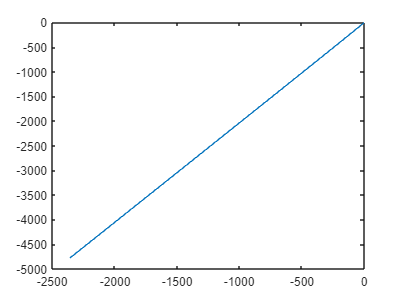

% Controllable subspace
theta_c = linspace(0,2000*pi,100);
r_c = 2*theta_c;


% trajectory of the system
syms t tau
time = linspace(0,1,100);
X = expm(A*t)*[-1 ; -1] + int(expm(A*(t-tau))*[3 ; 5],tau,0,t);

r_uc = double(subs(X(1),t,time));
theta_uc = double(subs(X(2),t,time));

%plot(theta_c,r_c)
%hold on
plot(theta_uc,r_uc)

#### Question 3.2.2

The docking can still be achieved with partial controls. In the graph, we can see that the trajectory is chaotic. However, the points where the trajectory of the system intersects with the controllable subspace are the points where the system can be controlled to tend to 0. The third actuator can be timed accordingly and its value can be calculated as follows.


$$e^{\textrm{At}} X\left(0\right)+\int_0^t e^{A\left(t-\tau \right)} B_{12} \;\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack \;d\tau +\int_0^t e^{A\left(t-\tau \right)} B_3 \;u_3 \;d\tau =0$$


This equation can be solved for u3 at the time instant where the 2 graphs intersect. Each intersection represents another opportunity to dock the vehicle.

#### Question 3.2.3

The equation of X = [delta_r ; delta_theta] can be solved against the y = 2x curve to see at what time instant, the trajectory enters the controllability subspace.


$$X\left(1\right)=2X\left(2\right)$$


This equation yields the time to be **0.32**. One point to note is that this time in independent of the control input which means it takes the same amount of time to dock regardless of which docking opportunity is exploited. This time is much less than 30 units of time. Therefore, the ISS mission would be safely finished.